## Load london

%Load london & combine into one single matrix
load London 
Prices.combined = [Prices.location Prices.rent];

## Clean data

%Clean data
Clean = Prices.combined(Prices.combined(:,1)>=51.31 & Prices.combined(:,1)<51.7, :);
Clean = Prices.combined(Prices.combined(:,2)>=-0.488 & Prices.combined(:,2)<0.225, :);

## 3D Plot

%3D plot with clean data
scatter3(Clean(:,2),Clean(:,1),Clean(:,3),9 ,Clean(:,3));
xlim([-0.5 0.23])
ylim([51.1 51.9])
xlabel('longitude[^\circ]')
ylabel('latitude[^\circ]')
zlabel('GBP PCM [£]')
hcb=colorbar

hcb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 27040]
    FontSize: 9
    Position: [0.8256 0.1100 0.0476 0.8150]
       Units: 'normalized'

  Show all properties


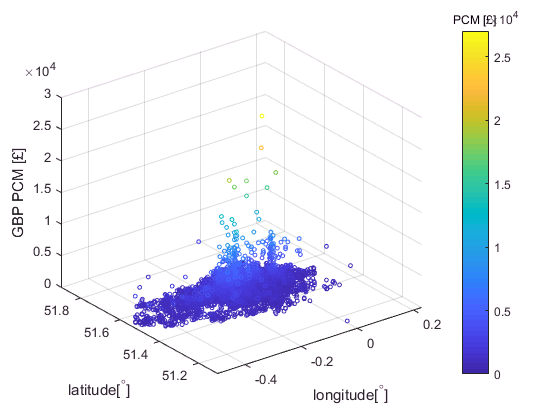

title(hcb,'PCM [£]')

## Split data into train and test data

%Randomly shuffle clean data (allows for cross-validation by repeating section
%shuffledclean=randperm(size(Clean,1));
for k=1:5
    section{1,k}=Clean([((1+(k-1)*(size(Clean)/5)):(k*size(Clean)/5)],:)
end 

Unbalanced or unexpected parenthesis or bracket.

Subscript indices must either be real positive integers or logicals.

trainData=Clean(shuffledclean(1:11638),:);
testData=Clean(shuffledclean(11639:14547),:);

## 3D plots with both train and test data

%Train
figure 
scatter3(trainData(:,3),trainData(:,2),trainData(:,1),'x','r');
xlabel('lat')
ylabel('long')
zlabel('GBP')
%Test
figure 
scatter3(testData(:,3),testData(:,2),testData(:,1),'x','r');
xlabel('lat')
ylabel('long')
zlabel('GBP')

## Train regressor

function [ param ] = trainRegressor(in, out)
in=trainDataLocation;
out=trainDataRent;
% Number of Guassian basis function
numGaussians = 7;
baseFuncs=cell(numGaussians+1,1);
% Initialising variables
[idx,C]=kmeans(trainDataLocation,7);
CLAT=C(:,1);
CLONG=C(:,2);
COV=cov(trainDataLocation);
for i=1:numGaussians
    % Fill your mean (mu) and variance (sig) here
    %===========================================%
    mu = [CLAT(i) CLONG(i)];
    sig = COV;
    %===========================================%
    baseFuncs{i}=@(x)myGaussian(x,mu,sig);
    param.mu{i}=mu;
    param.sig{i}=sig;
end
baseFuncs{end}=@(x)1;
%calculate the values of each basis function at each training datapoint
val=zeros(length(in),length(baseFuncs));
parfor i=1:length(in)
    valTemp=zeros(1,length(baseFuncs));
    for j=1:length(baseFuncs)
        valTemp(1,j)=baseFuncs{j}(in(i,:));
    end
    val(i,:)=valTemp;
end
%pseudoinverse for least squares solution
param.w=pinv(val)*out;
param.baseFuncs=baseFuncs;
end

function val=myGaussian(x,mu,sig)
%a gaussian basis function
val=exp(-(x-mu)*sig*(x-mu)');
end